**Genetic programming**


$$${minimize}f(\textbf{x})$ subject to $\left\{\begin{array}{l}g_{j}(\textbf{x}) \leq 0 \\ h_{k}(\textbf{x})=0 \\ \textbf{G} . \textbf{x} \leq \textbf{A} \\ \textbf{H} . \textbf{x}=\textbf{B} \\ \textbf{L} \leq \textbf{x} \leq \textbf{U} \\ \widehat\textbf{x}: \hat{x}_{l} \in \textbf{x}\end{array}\right.$$$


**Different annotations**


$$$\min f(x)$ such that $\left\{\begin{array}{l}c(x) \leq 0 \\ c e q \leq 0 \\ A \cdot x \leq 0 \\ \text { Aeq. } x=b e q \\ l b \leq x \leq u b \\ \text { IntCon }\end{array}\right.$$$


**Usage**

**Problem**


$$${minimize} f(x)=\sum_{i=1}^{N} x_{i}$ subject to $\left\{\begin{array}{l}1 \leq x_{1}, x_{2}, \ldots, x_{N} \leq 2 \pi \\ \cos \left(\prod_{i=1}^{N} x_{i}\right) \sin \left(\prod_{i=1}^{N} \frac{1}{x_{i}}\right)-\frac{1}{2} \leq 0 \\ \hat{\textbf{x}}=\left[x_{3}, x_{4}, x_{5}\right]\end{array}\right.$$$


Define parameters and run ga

clc
clear
close all
warning off

% Define parameters 
nvars       = 75;
x_initial   = rand(1,nvars)/10;
IntCon      = [3,4,5]

IntCon =      3     4     5


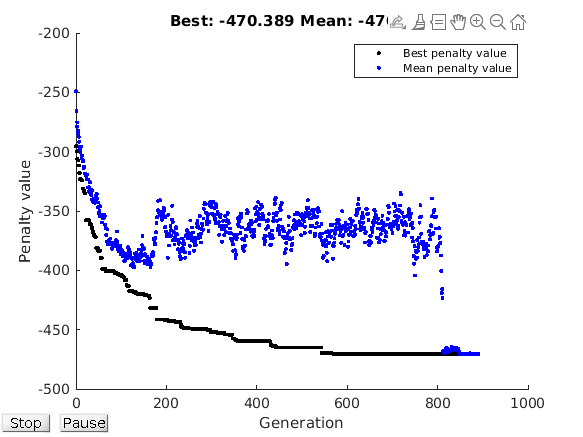

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


x =     6.2832    6.2832    6.0000    6.0000    6.0000    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832    6.2832


f_val = -470.3893

A           = [];
b           = [];
Aeq         = [];
beq         = [];
lb          = ones(1,nvars);
ub          = ones(1,nvars)*2*pi;
PopSize     = 50;
GenSize     = 1000;
options     = optimoptions('ga', ...
                           'ConstraintTolerance',1e-128, ...
                           'FunctionTolerance',1e-128, ...
                           'PlotFcn', @gaplotbestf, ...
                           'PopulationSize',PopSize, ...
                           'InitialPopulationMatrix',x_initial, ...
                           'MaxGenerations',GenSize);
                       
nonlcon     = @fun_cosntraints;
fun         = @fun_objective;

% Run ga
[x, f_val] = ga(fun, nvars, A, b, Aeq, beq, lb, ub, nonlcon, IntCon, options)

Define functions 

% Define objective function

function f = fun_objective(x)
    f = -sum(x);
end

% Define constraints
% -Inequality
function g = fun_constraint1(x)
    g = cos(prod(x))*sin(prod(1./x));
end

% Combine based on online descriptions
function [g, h] = fun_cosntraints(x)
    g = fun_constraint1(x); 
    h = [];
end